# CẤU HÌNH CHUNG

% Đường dẫn dữ liệu và nơi lưu kết quả
baseDir = "C:\Users\LENOVO\Desktop\image_processing\giuaki\data";
outDir  = "C:\Users\LENOVO\Desktop\image_processing\giuaki";
out3Dir = "C:\Users\LENOVO\Desktop\image_processing\giuaki\anhbai3";
out1Dir = "C:\Users\LENOVO\Desktop\image_processing\giuaki\anhbai1";
% Các định dạng ảnh được hỗ trợ
exts = [".png", ".jpg", ".jpeg", ".bmp", ".tiff", ".tif"];

% Bộ lọc theo Alleysson
FL = [-2  3  -6  3  -2;
       3  4   2  4   3;
      -6  2  48  2  -6;
       3  4   2  4   3;
      -2  3  -6  3  -2] / 64;  % Luminance filter

Frb = [1 2 1; 2 4 2; 1 2 1] / 4; % Nội suy cho R/B
Fg  = [0 1 0; 1 4 1; 0 1 0] / 4; % Nội suy cho G

disp("✓ Đã khởi tạo cấu hình");

✓ Đã khởi tạo cấu hình


%% BÀI 1 - QUÉT DANH SÁCH ẢNH
files = dir(baseDir);
files = files(~[files.isdir]);
imgNames = {};

for k = 1:numel(files)
    [~, ~, e] = fileparts(files(k).name);
    if any(strcmpi(e, exts))
        imgNames{end+1} = files(k).name;
    end
end

nImgs = numel(imgNames);
results = NaN(nImgs, 4);
perImage = strings(nImgs, 1);
ri = 0;

fprintf("✓ Đã quét %d ảnh RGB", nImgs);

✓ Đã quét 18 ảnh RGB

disp(imgNames');

    {'1.tif' }
    {'10.tif'}
    {'11.tif'}
    {'12.tif'}
    {'13.tif'}
    {'14.tif'}
    {'15.tif'}
    {'16.tif'}
    {'17.tif'}
    {'18.tif'}
    {'2.tif' }
    {'3.tif' }
    {'4.tif' }
    {'5.tif' }
    {'6.tif' }
    {'7.tif' }
    {'8.tif' }
    {'9.tif' }



## BÀI 1 - XỬ LÝ DEMOSAICING CHO TỪNG ẢNH


━━━ Xử lý 1/18: 1.tif ━━━


  📊 Bilinear:  PSNR = 26.64 dB | SSIM = 0.948


  📊 Alleysson: PSNR = 25.64 dB | SSIM = 0.950


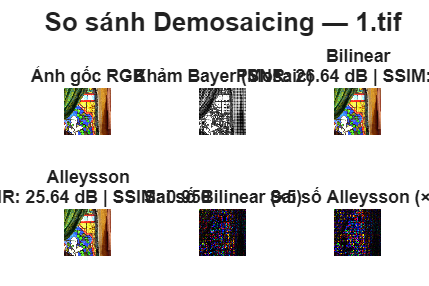


━━━ Xử lý 2/18: 10.tif ━━━


  📊 Bilinear:  PSNR = 33.38 dB | SSIM = 0.985


  📊 Alleysson: PSNR = 33.87 dB | SSIM = 0.987



━━━ Xử lý 3/18: 11.tif ━━━


  📊 Bilinear:  PSNR = 34.77 dB | SSIM = 0.983


  📊 Alleysson: PSNR = 34.78 dB | SSIM = 0.982



━━━ Xử lý 4/18: 12.tif ━━━


  📊 Bilinear:  PSNR = 30.78 dB | SSIM = 0.982


  📊 Alleysson: PSNR = 34.33 dB | SSIM = 0.993



━━━ Xử lý 5/18: 13.tif ━━━


  📊 Bilinear:  PSNR = 32.35 dB | SSIM = 0.983


  📊 Alleysson: PSNR = 36.46 dB | SSIM = 0.993



━━━ Xử lý 6/18: 14.tif ━━━


  📊 Bilinear:  PSNR = 33.32 dB | SSIM = 0.978


  📊 Alleysson: PSNR = 35.17 dB | SSIM = 0.983



━━━ Xử lý 7/18: 15.tif ━━━


  📊 Bilinear:  PSNR = 33.71 dB | SSIM = 0.983


  📊 Alleysson: PSNR = 35.42 dB | SSIM = 0.987



━━━ Xử lý 8/18: 16.tif ━━━


  📊 Bilinear:  PSNR = 30.32 dB | SSIM = 0.975


  📊 Alleysson: PSNR = 28.78 dB | SSIM = 0.970



━━━ Xử lý 9/18: 17.tif ━━━


  📊 Bilinear:  PSNR = 32.04 dB | SSIM = 0.978


  📊 Alleysson: PSNR = 27.86 dB | SSIM = 0.949



━━━ Xử lý 10/18: 18.tif ━━━


  📊 Bilinear:  PSNR = 28.97 dB | SSIM = 0.959


  📊 Alleysson: PSNR = 31.50 dB | SSIM = 0.974



━━━ Xử lý 11/18: 2.tif ━━━


  📊 Bilinear:  PSNR = 30.38 dB | SSIM = 0.952


  📊 Alleysson: PSNR = 32.05 dB | SSIM = 0.963



━━━ Xử lý 12/18: 3.tif ━━━


  📊 Bilinear:  PSNR = 25.69 dB | SSIM = 0.901


  📊 Alleysson: PSNR = 31.33 dB | SSIM = 0.966



━━━ Xử lý 13/18: 4.tif ━━━


  📊 Bilinear:  PSNR = 26.71 dB | SSIM = 0.924


  📊 Alleysson: PSNR = 33.03 dB | SSIM = 0.980



━━━ Xử lý 14/18: 5.tif ━━━


  📊 Bilinear:  PSNR = 30.27 dB | SSIM = 0.955


  📊 Alleysson: PSNR = 30.18 dB | SSIM = 0.959



━━━ Xử lý 15/18: 6.tif ━━━


  📊 Bilinear:  PSNR = 33.02 dB | SSIM = 0.964


  📊 Alleysson: PSNR = 31.75 dB | SSIM = 0.948



━━━ Xử lý 16/18: 7.tif ━━━


  📊 Bilinear:  PSNR = 29.51 dB | SSIM = 0.864


  📊 Alleysson: PSNR = 36.78 dB | SSIM = 0.971



━━━ Xử lý 17/18: 8.tif ━━━


  📊 Bilinear:  PSNR = 30.09 dB | SSIM = 0.940


  📊 Alleysson: PSNR = 35.94 dB | SSIM = 0.973



━━━ Xử lý 18/18: 9.tif ━━━


  📊 Bilinear:  PSNR = 31.20 dB | SSIM = 0.977


  📊 Alleysson: PSNR = 32.76 dB | SSIM = 0.982


if ~exist(out1Dir, 'dir')
    mkdir(out1Dir);
end

for idx = 1:nImgs
    fn = imgNames{idx};
    fprintf("\n━━━ Xử lý %d/%d: %s ━━━\n", idx, nImgs, fn);
    
    % Đọc ảnh
    I = imread(fullfile(baseDir, fn));
    if ndims(I) ~= 3 || size(I,3) ~= 3
        fprintf("  ⚠ Bỏ qua (không phải RGB)\n");
        continue;
    end
    I = im2double(I);
    [h, w, ~] = size(I);
    
    % Tạo mặt nạ Bayer RGGB
    mR = zeros(h, w); mR(1:2:end, 1:2:end) = 1;
    mB = zeros(h, w); mB(2:2:end, 2:2:end) = 1;
    mG = 1 - mR - mB;
    
    % Tạo mosaic
    Mosaic = I(:,:,1).*mR + I(:,:,2).*mG + I(:,:,3).*mB;
    
    % === PHƯƠNG PHÁP ALLEYSSON ===
    L = imfilter(Mosaic, FL, 'replicate');
    Chr = Mosaic - L;
    ChrR_i = imfilter(Chr .* mR, Frb, 'replicate');
    ChrG_i = imfilter(Chr .* mG, Fg, 'replicate');
    ChrB_i = imfilter(Chr .* mB, Frb, 'replicate');
    All = cat(3, L + ChrR_i, L + ChrG_i, L + ChrB_i);
    All = min(max(All, 0), 1);
    
    % === PHƯƠNG PHÁP BILINEAR ===
    RB = imfilter(Mosaic .* mR, Frb, 'replicate');
    GB = imfilter(Mosaic .* mG, Fg, 'replicate');
    BB = imfilter(Mosaic .* mB, Frb, 'replicate');
    Bil = cat(3, RB, GB, BB);
    Bil = min(max(Bil, 0), 1);
    
    % Tính chỉ số chất lượng
    try
        psnr_B = psnr(Bil, I);
        psnr_A = psnr(All, I);
        ssim_B = ssim(Bil, I);
        ssim_A = ssim(All, I);
    catch
        psnr_B = localPSNR(I, Bil);
        psnr_A = localPSNR(I, All);
        ssim_B = NaN;
        ssim_A = NaN;
    end
    
    % Lưu kết quả
    ri = ri + 1;
    results(ri, :) = [psnr_B, ssim_B, psnr_A, ssim_A];
    perImage(ri, 1) = string(fn);
    
    fprintf("  📊 Bilinear:  PSNR = %.2f dB | SSIM = %.3f\n", psnr_B, ssim_B);
    fprintf("  📊 Alleysson: PSNR = %.2f dB | SSIM = %.3f\n", psnr_A, ssim_A);
    
    % Tạo figure (hiển thị nếu là ảnh đầu tiên, ẩn nếu không)
    if idx == 1
        fig = figure('Color', 'w', 'Position', [100 100 1200 800]);
    else
        fig = figure('Color', 'w', 'Position', [100 100 1200 800], 'Visible', 'off');
    end
    
    tiledlayout(fig, 2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    nexttile; imshow(I); title('Ảnh gốc RGB', 'FontWeight', 'bold');
    nexttile; imshow(Mosaic, []); colormap(gca, gray); title('Khảm Bayer (Mosaic)', 'FontWeight', 'bold');
    nexttile; imshow(Bil); title(sprintf('Bilinear\nPSNR: %.2f dB | SSIM: %.3f', psnr_B, ssim_B));
    
    nexttile; imshow(All); title(sprintf('Alleysson\nPSNR: %.2f dB | SSIM: %.3f', psnr_A, ssim_A));
    
    errB = min(abs(I - Bil) * 5, 1);
    nexttile; imshow(errB); title('Sai số Bilinear (×5)');
    
    errA = min(abs(I - All) * 5, 1);
    nexttile; imshow(errA); title('Sai số Alleysson (×5)');
    
    sgtitle(sprintf('So sánh Demosaicing — %s', fn), 'FontWeight', 'bold');
    
    % Lưu hình vào thư mục anhbai1
    exportgraphics(fig, fullfile(out1Dir, sprintf('McM_comparison_%d.png', idx)), 'Resolution', 150);
    
    % Đóng figure nếu không phải ảnh đầu
    if idx > 1
        close(fig);
    end
end

fprintf("\n✓ Đã lưu tất cả hình vào: %s\n", out1Dir);


✓ Đã lưu tất cả hình vào: C:\Users\LENOVO\Desktop\image_processing\giuaki\anhbai1



% Cắt phần thừa
if ri < nImgs
    results = results(1:ri, :);
    perImage = perImage(1:ri, :);
end


## BÀI 1 - BẢNG KẾT QUẢ

T = table(perImage, results(:,1), results(:,2), results(:,3), results(:,4), ...
    'VariableNames', {'Image', 'Bilinear_PSNR', 'Bilinear_SSIM', 'Alleysson_PSNR', 'Alleysson_SSIM'});

if ~isempty(results)
    avgVals = round(mean(results, 1), 3);
    T = [T; {"Average", avgVals(1), avgVals(2), avgVals(3), avgVals(4)}];
end

disp(T);

      Image      Bilinear_PSNR    Bilinear_SSIM    Alleysson_PSNR    Alleysson_SSIM
    _________    _____________    _____________    ______________    ______________

    "1.tif"         26.636           0.94821           25.639           0.94983    
    "10.tif"        33.377            0.9849           33.873           0.98654    
    "11.tif"        34.765            0.9835           34.779           0.98212    
    "12.tif"        30.778           0.98229            34.33            0.9927    
    "13.tif"        32.348           0.98289           36.461           0.99283    
    "14.tif"        33.324           0.97799           35.167           0.98341    
    "15.tif"        33.707           0.98298           35.415           0.98726    
    "16.tif"         30.32           0.97474           28.779            

% Lưu Excel
try
    writetable(T, fullfile(outDir, "McM_demosaicing_results.xlsx"));
    fprintf("\n✓ Đã lưu Excel\n");
catch ME
    warning("Không thể lưu Excel: %s", ME.message);
end


✓ Đã lưu Excel


## BÀI 1 - BIỂU ĐỒ SO SÁNH

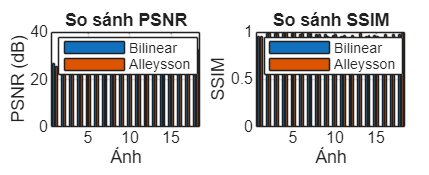

if ~isempty(results)
    figure('Color', 'w', 'Position', [100 100 1100 450]);
    tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    nexttile;
    bar([results(:,1), results(:,3)]);
    xlabel('Ảnh'); ylabel('PSNR (dB)');
    title('So sánh PSNR');
    legend({'Bilinear', 'Alleysson'}, 'Location', 'best');
    grid on;
    
    nexttile;
    bar([results(:,2), results(:,4)]);
    xlabel('Ảnh'); ylabel('SSIM');
    title('So sánh SSIM');
    legend({'Bilinear', 'Alleysson'}, 'Location', 'best');
    grid on;
    
    exportgraphics(gcf, fullfile(outDir, "McM_performance_chart.png"), 'Resolution', 150);
end

if ~isempty(results)
    n = size(results, 1);
    avg = mean(results, 1);
    fprintf("📌 Số lượng ảnh xử lý: %d\n", n);
    fprintf("📊 Trung bình Bilinear:  PSNR = %.2f dB | SSIM = %.3f\n", avg(1), avg(2));
    fprintf("📊 Trung bình Alleysson: PSNR = %.2f dB | SSIM = %.3f\n", avg(3), avg(4));
    fprintf("📈 Cải thiện: ΔPSNR = %+0.2f dB | ΔSSIM = %+0.3f\n", avg(3)-avg(1), avg(4)-avg(2));
end

📌 Số lượng ảnh xử lý: 18


📊 Trung bình Bilinear:  PSNR = 30.73 dB | SSIM = 0.957


📊 Trung bình Alleysson: PSNR = 32.64 dB | SSIM = 0.973


📈 Cải thiện: ΔPSNR = +1.91 dB | ΔSSIM = +0.016


## BÀI 2 - HOÁN ĐỔI BIÊN ĐỘ & PHA FOURIER


━━━ BÀI 2: Xử lý 1.tif & 2.tif ━━━


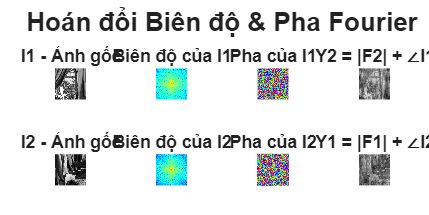

✓ Đã lưu: fourier_swap_result.png


f1 = fullfile(baseDir, "1.tif");
f2 = fullfile(baseDir, "2.tif");

if isfile(f1) && isfile(f2)
    fprintf("\n━━━ BÀI 2: Xử lý 1.tif & 2.tif ━━━\n");
    
    % Đọc và tiền xử lý
    I1 = imread(f1); if size(I1,3)==3, I1 = rgb2gray(I1); end
    I2 = imread(f2); if size(I2,3)==3, I2 = rgb2gray(I2); end
    
    % Resize về cùng kích thước
    h = min(size(I1,1), size(I2,1));
    w = min(size(I1,2), size(I2,2));
    I1 = imresize(I1, [h w]);
    I2 = imresize(I2, [h w]);
    
    % Biến đổi Fourier
    F1 = fft2(double(I1));
    F2 = fft2(double(I2));
    
    mag1 = abs(F1); ph1 = angle(F1);
    mag2 = abs(F2); ph2 = angle(F2);
    
    % Hoán đổi
    Y1 = mag1 .* exp(1i * ph2); y1 = real(ifft2(Y1));
    Y2 = mag2 .* exp(1i * ph1); y2 = real(ifft2(Y2));
    
    % Hiển thị
    figure('Color', 'w', 'Position', [100 100 1200 600]);
    tiledlayout(2, 4, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    nexttile; imshow(I1, []); title('I1 - Ảnh gốc', 'FontWeight', 'bold');
    nexttile; imshow(log(1 + fftshift(mag1)), []); title('Biên độ của I1'); colormap(gca, jet);
    nexttile; imshow(fftshift(ph1), []); title('Pha của I1'); colormap(gca, hsv);
    nexttile; imshow(y2, []); title('Y2 = |F2| + ∠I1', 'FontWeight', 'bold');
    
    nexttile; imshow(I2, []); title('I2 - Ảnh gốc', 'FontWeight', 'bold');
    nexttile; imshow(log(1 + fftshift(mag2)), []); title('Biên độ của I2'); colormap(gca, jet);
    nexttile; imshow(fftshift(ph2), []); title('Pha của I2'); colormap(gca, hsv);
    nexttile; imshow(y1, []); title('Y1 = |F1| + ∠I2', 'FontWeight', 'bold');
    
    sgtitle('Hoán đổi Biên độ & Pha Fourier', 'FontWeight', 'bold');
    exportgraphics(gcf, fullfile(outDir, "fourier_swap_result.png"), 'Resolution', 150);
    
    fprintf("✓ Đã lưu: fourier_swap_result.png\n");
else
    fprintf("⚠ BỎ QUA BÀI 2: Thiếu file 1.tif hoặc 2.tif\n");
end

## BÀI 3 - PHỔ BIÊN ĐỘ CHO 2 ẢNH

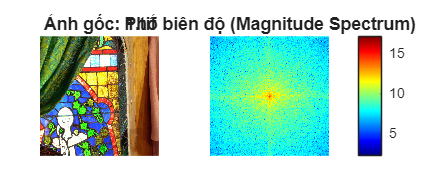

✓ Đã lưu: spectrum_1.png


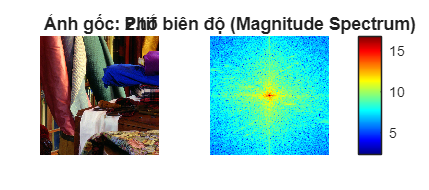

✓ Đã lưu: spectrum_2.png


filesToProcess = ["1.tif", "2.tif"];

for fn = filesToProcess
    fpath = fullfile(out3Dir, fn);
    
    if ~isfile(fpath)
        warning("Không tìm thấy: %s", fpath);
        continue;
    end
    
    % Đọc và chuyển grayscale
    I = imread(fpath);
    if ndims(I) == 3
        Igray = rgb2gray(I);
    else
        Igray = I;
    end
    
    % Tính phổ biên độ
    F = fft2(double(Igray));
    Fshift = fftshift(F);
    spectrum = log(1 + abs(Fshift));
    
    % Hiển thị
    figure('Color', 'w', 'Position', [100 100 900 400]);
    tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    nexttile; imshow(I, []); title("Ảnh gốc: " + fn, 'FontWeight', 'bold');
    nexttile; imagesc(spectrum); axis image off; 
    title("Phổ biên độ (Magnitude Spectrum)"); 
    colormap(jet); colorbar;
    
    % Lưu
    [~, name] = fileparts(fn);
    outName = fullfile(out3Dir, "spectrum_" + name + ".png");
    exportgraphics(gcf, outName, 'Resolution', 150);
    
    fprintf("✓ Đã lưu: spectrum_%s.png\n", name);
end

%% HÀM PHỤ TRỢ
function val = localPSNR(ref, est)
    % Tính PSNR khi không có Image Processing Toolbox
    ref = im2double(ref);
    est = im2double(est);
    mse = mean((ref(:) - est(:)).^2);
    if mse == 0
        val = Inf;
    else
        val = 10 * log10(1 / mse);
    end
end